syms m a g theta(t)
eqn = m*a == -m*g*sin(theta)

$$eqn(t) = a\,m=-g\,m\,\sin\left(\theta \left(t\right)\right)$$

syms r
eqn = subs(eqn,a,r*diff(theta,2))

$$eqn(t) = m\,r\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-g\,m\,\sin\left(\theta \left(t\right)\right)$$

eqn = isolate(eqn,diff(theta,2))

$$eqn = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{g\,\sin\left(\theta \left(t\right)\right)}{r}$$

syms omega_0
eqn = subs(eqn,g/r,omega_0^2)

$$eqn = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-{\omega_{0}}^{2}\,\sin\left(\theta \left(t\right)\right)$$

syms x
approx = taylor(sin(x),x,'Order',2);
approx = subs(approx,x,theta(t))

$$approx = \theta \left(t\right)$$

eqnLinear = subs(eqn,sin(theta(t)),approx)

$$eqnLinear = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-{\omega_{0}}^{2}\,\theta \left(t\right)$$

syms theta_0 theta_t0
theta_t = diff(theta);
cond = [theta(0) == theta_0, theta_t(0) == theta_t0];
assume(omega_0,'real')
thetaSol(t) = dsolve(eqnLinear,cond)

$$thetaSol(t) = \theta_{0}\,\cos\left(\omega_{0}\,t\right)+\frac{\theta_{\mathrm{t0}}\,\sin\left(\omega_{0}\,t\right)}{\omega_{0}}$$

gValue = 9.81;
rValue = 0.25;
omega_0Value = sqrt(gValue/rValue);
T = 2*pi/omega_0Value;

theta_0Value  = 0.1*pi; % Solution only valid for small angles.
theta_t0Value = 0;      % Initially at rest.

vars   = [omega_0      theta_0      theta_t0];
values = [omega_0Value theta_0Value theta_t0Value];
thetaSolPlot = subs(thetaSol,vars,values);

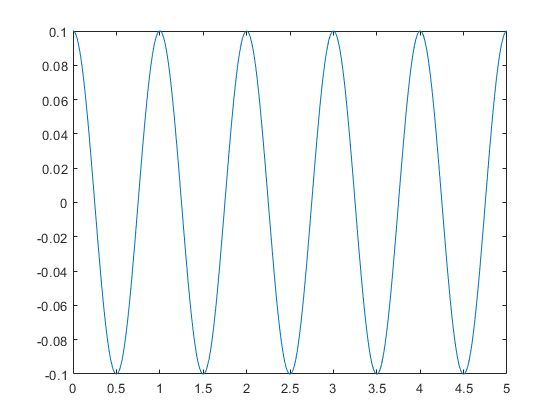

fplot(thetaSolPlot(t*T)/pi, [0 5]);

grid on;
title('Harmonic Pendulum Motion');
xlabel('t/T');
ylabel('\theta/\pi');

newfig=figure

newfig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


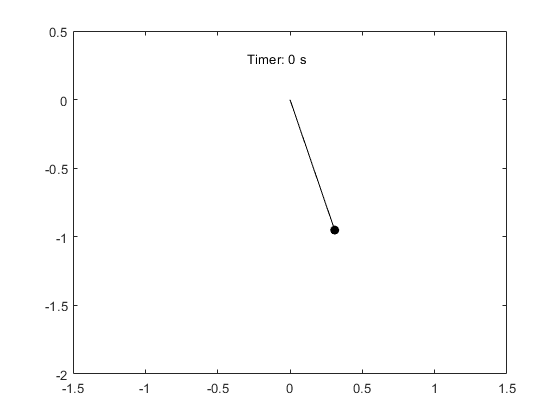

x_pos = sin(thetaSolPlot);
y_pos = -cos(thetaSolPlot);
fanimator(@fplot,x_pos,y_pos,'ko','MarkerFaceColor','k','AnimationRange',[0 5*T]);
hold on;
fanimator(@(t) plot([0 x_pos(t)],[0 y_pos(t)],'k-'),'AnimationRange',[0 5*T]);
fanimator(@(t) text(-0.3,0.3,"Timer: "+num2str(t,2)+" s"),'AnimationRange',[0 5*T]);

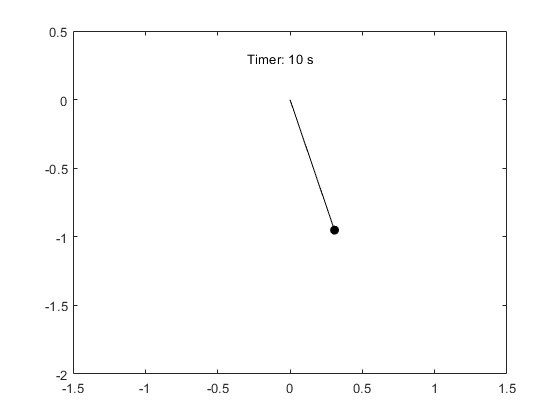

playAnimation

hold off;

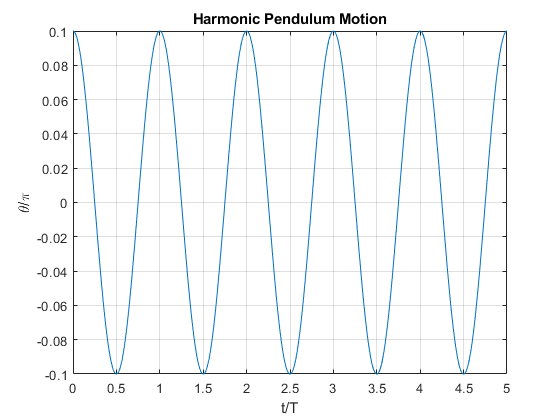

rValue = 0.25;
fplot(thetaSolPlot(t*T)/pi, [0 5]);
grid on;
title('Harmonic Pendulum Motion');
xlabel('t/T');
ylabel('\theta/\pi');